% prob 1
theta = pi / 3

theta = 1.0472

rmg = [cos(theta) sin(theta); -sin(theta) cos(theta)];
rmm = [cos(theta) -sin(theta); sin(theta) cos(theta)];
ptg = [2;-1];
ptm = rmg * ptg

ptm =     0.1340
   -2.2321


pt2m = [3;-2];
pt2g = inv(rmg) * pt2m

pt2g =     3.2321
    1.5981



m1hat = [cos(theta); sin(theta)]

m1hat =     0.5000
    0.8660


m2hat = [-sin(theta); cos(theta)]

m2hat =    -0.8660
    0.5000


% prob 2
theta = pi / 3

theta = 1.0472

rmg = [cos(pi/3) sin(pi/3) 0; -sin(pi/3) cos(pi/3) 0; 0 0 1];
tmg = [1 0 3;0 1 -1; 0 0 1];
m1hat = [cos(theta)-3; sin(theta)+1]

m1hat =    -2.5000
    1.8660


m2hat = [-sin(theta)-3; cos(theta)+1]

m2hat =    -3.8660
    1.5000


pt1g = [2;-1; 1];
pt2m = [3;-2; 1];
pt1m = rmg * tmg * pt1g

pt1m =     0.7679
   -5.3301
    1.0000


pt2g = inv(tmg) * inv(rmg) * pt2m

pt2g =     0.2321
    2.5981
    1.0000


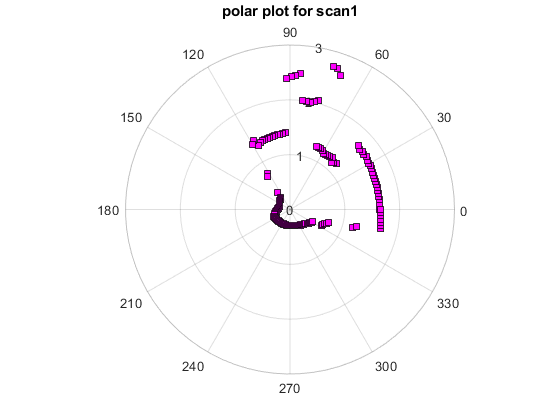

% prob 6

%load data
data = load('rall.mat');
r_all = data.r_all;
t1 = r_all(:,1);
t1t = [1:1:360]';
t2 = r_all(:,2);
t2t = [1:1:360]';
t3 = r_all(:,3);
t3t = [1:1:360]';
t4 = r_all(:,4);
t4t = [1:1:360]';


t1t(~t1) = [];
t1 = nonzeros(t1);
t2t(~t2) = [];
t2 = nonzeros(t2);
t3t(~t3) = [];
t3 = nonzeros(t3);
t4t(~t4) = [];
t4 = nonzeros(t4);

%clean the data
% t1_rc = nonzeros(t1);
% t2_rc = nonzeros(t2);
% t3_rc = nonzeros(t3);
% t4_rc = nonzeros(t4);

% plot to confirm data quality
figure()
polarplot(t1,'ks',...
    'MarkerSize',6,'MarkerFaceColor','m')
title('polar plot for scan1')


% transform to global
% phi
t1l = [t1 .* cosd(t1t), t1 .* sind(t1t), ones(length(t1),1)];
d = 0.1143 %meters

d = 0.1143

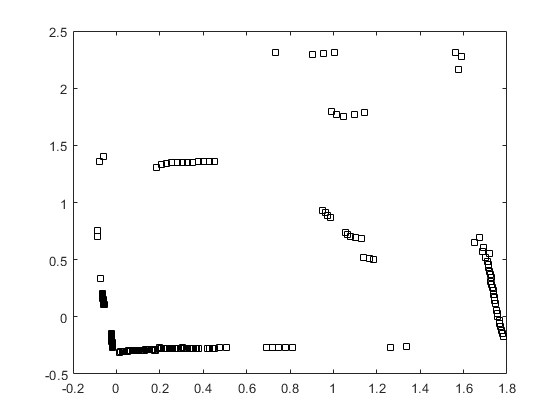

t1n = [1 0 d; 0 1 0; 0 0 1] * t1l';
xn = 0;
yn = 0;
phi = 0;
t1g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(0),-sind(0),0;sind(0),cosd(0),0;0,0,1] * t1n;
figure()
plot(t1g(1,:),t1g(2,:),'ks')

t2l = [t2 .* cosd(t2t), t2 .* sind(t2t), ones(length(t2),1)];
d = 0.1143 %meters

d = 0.1143

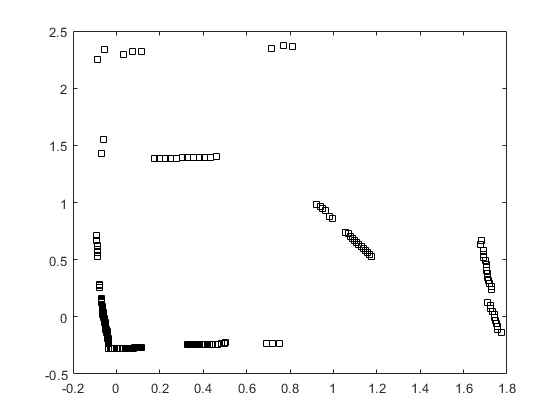

t2n = [1 0 d; 0 1 0; 0 0 1] * t2l';
xn = 0.20;
yn = -0.20;
phi = 90;
t2g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t2n;
figure()
plot(t2g(1,:),t2g(2,:),'ks')

t3l = [t3 .* cosd(t3t), t3 .* sind(t3t), ones(length(t3),1)];
d = 0.1143 %meters

d = 0.1143

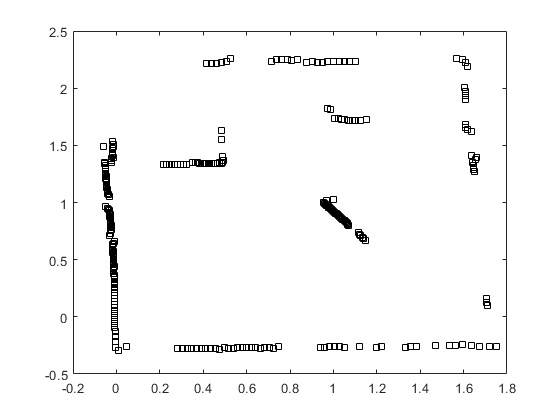

t3n = [1 0 d; 0 1 0; 0 0 1] * t3l';
xn = 0.508;
yn = 0.9144;
phi = 0;
t3g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t3n;
figure()
plot(t3g(1,:),t3g(2,:),'ks')

t4l = [t4 .* cosd(t4t), t4 .* sind(t4t), ones(length(t4),1)];
d = 0.1143 %meters

d = 0.1143

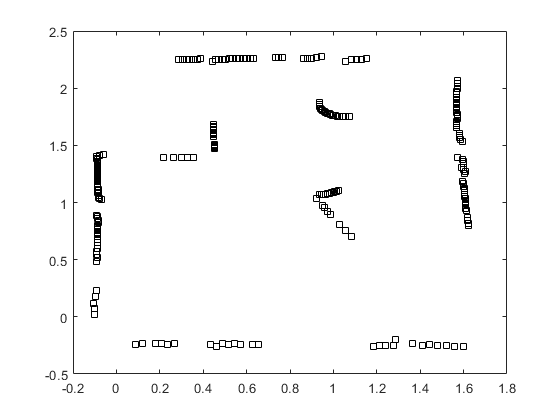

t4n = [1 0 d; 0 1 0; 0 0 1] * t4l';
xn = 0.508;
yn = 1.2716;
phi = 36;
t4g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t4n;
figure()
plot(t4g(1,:),t4g(2,:),'ks')

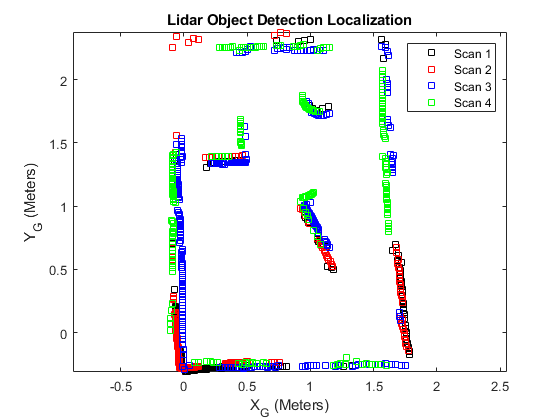

figure()
plot(t1g(1,:),t1g(2,:),'ks'), hold on
plot(t2g(1,:),t2g(2,:),'rs')
plot(t3g(1,:),t3g(2,:),'bs')
plot(t4g(1,:),t4g(2,:),'gs')
xlabel('X_{G} (Meters)')
ylabel('Y_{G} (Meters)')
title('Lidar Object Detection Localization')
legend('Scan 1','Scan 2', 'Scan 3', 'Scan 4')
axis equal